# Neural network for regression and k-class classification

## Neural Networks for k-class classification problems

Now that we have seen how a shallow neural network works with a binary classification problem, let's extend our approach to a k-class classification problem to the Cleveland heart disease dataset. 

### Load the cleveland dataset

Recall that the dataset has 5 different classes for disease heart disease severity, where 0 is no disease and 4 is high risk. 

clear all; cleveland = readtable('cleveland.xlsx')

First, we need to split the dataset into a training and testing set.

% Initialize params for trainTestSplit
trainingSize = 0.8; randomstate = 2;

% Split the dataset into training and test sets.
[Xtrain, Ytrain, Xtest, Ytest] = ...
    trainTestSplit(cleveland(:, 1:end-1), cleveland(:, end), ...
    trainingSize, randomstate);
validation = Ytest;

Next, we need to standardize the dataset:

% Standardize the dataset with mean = 0 and standard deviation = 1. 
mu = mean(Xtrain); sigma = std(Xtrain);
Xtrain = (Xtrain - mu) ./ sigma; Xtest  = (Xtest - mu)  ./ sigma; % Use the same mu and sigma -> assume same distribution

### One-hot encoding for k-class classification problems

Finally, let's expand our single column to an array, where the value 1 in each column corresponds to whether or not the observation belongs to a specific class. This method of label-encoding is called **one-hot encoding**.

% Initialize our arrays. Because there are 5 classes, we need to make an n
% x 5 array
kclasses  = length(unique(Ytest));
tmpYtrain = zeros(size(Ytrain, 1), kclasses); tmpYtest  = zeros(size(Ytest, 1), kclasses);

% Make new response arrays. Note that the classes were originally between 0
% and 4.
for i = 1:kclasses
    tmpYtrain(:, i) = (Ytrain == (i - 1)); tmpYtest(:, i)  = (Ytest == (i - 1));
end
Ytrain = tmpYtrain; Ytest = tmpYtest; % Set the new Ytrain and Ytest variables
Ytrain                                % Show only Ytrain

We need to transpose the dataset so that the features span the rows and the columns span the observations.

Xtrain = Xtrain'; Ytrain = Ytrain'; Xtest = Xtest'; Ytest = Ytest';

### Initialize model hyperparameters

Next, let's initialize some model hyperparameters in order to train the model, including the optimization algorithm, network structure, and number of epochs. We'll assume that 5 activation nodes in the hidden layer will be sufficient enough to output decent predictions.

numOfActivationNodes = [5];                                   % 1 hidden layer with 5 activation nodes
optimizationFnc      = 'traingd';                                              % Gradient descent optimization algorithm
net                  = patternnet(numOfActivationNodes, optimizationFnc);  % Construct a shallow feedforward neural network with 5 activation nodes
net.divideParam.trainRatio = 0.2;                                              % Training set size = 60%
net.trainParam.epochs      = 5000;                                            % Number of epochs = 10,000

### Train the shallow feedforward neural network

Finally, we can train the neural network and output the trained model, as well as model metrics using the `train` function. 

[trainedNet, trainingRecord] = train(net, Xtrain, Ytrain);                      % Train the model

### Computed predicted label values using the trained neural network

Let's now output our predicted values using the `trainedNet` object, which acts as a function as well.

ypred = trainedNet(Xtest)

Now that we have the predicted values from the neural network value, we need to label encode these values. One natural question that you may be wondering is, how do we decide the best heart disease severity class for an individual patient? We'll discuss the generalized form of the log-loss activation function, which is known as the softmax activation function.  

### The softmax activation function

#### Intuition of the softmax activation function

The sigmoid activation function expression transforms values into probabilities using the following expression:$A=\frac{1}{1+e^{-Z} }$. If Z is very large, the expression moves towards 1, while if Z is very small, the expression moves towards 0. This allows us to transform values to assume a binary distribution, and gives us a natural decision boundary: $p=0\ldotp 5$. 

The question now then, is how do we draw multiple decision boundaries for a k-class problem? One method is to transform the outputs from the neural network from 0 to 1 using exponential terms. This returns us probabilities. Then, we choose to label encode an observation to a particular class with the maximum probability that it belongs to a given class. This is known as the **softmax activation function**, and it is the generalized form of the log-loss activation function for $k$-class classification problems. 

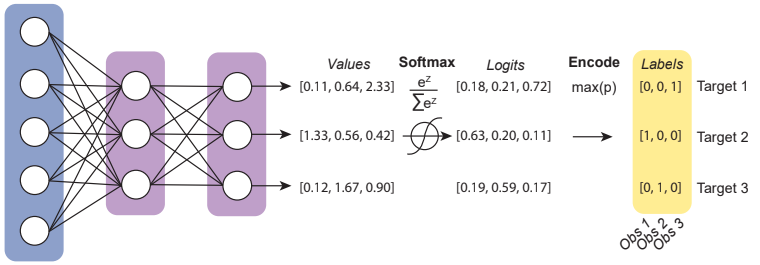

#### Formulation of the softmax activation function

The formulation of the softmax activation function is shown below:

$y_{\textrm{pred}} =\frac{e^{Z_k } }{\underset{k}{\sum e^{Z_k } } }$ where $k$ denotes a specific class. 

The specific problem we're trying to solve is create probabilities for whether or not a patient has heart disease of a given severity level. The following code block will perform the softmax activation function to transform our values to probabilities for the k-class case.

% Softmax activation function
ypred = exp(ypred) ./ sum(exp(ypred))

Each column will sum up to 1, indiciating that we have successfully transformed the model output to probabilities. Using the maximum probability, we'll assign the patient a given heart disease severity level. In the case for the first patient (first column), we'll assign their heart disease risk a value of 0 (first row), indicating no risk. 

To codify this process, the code block below finds the maximum value in each column, and sets it equal to 1, while the other values are set to 0. Then we will label encode each class in the predicted values and the test set with value of 1 through 5 (1 = 0 severity, 2 = 1 severity, etc). 

% Set maximum value in each column as 1, while the other values are set to
% 0
ypred(ypred == max(ypred)) = 1; 
ypred(ypred ~= max(ypred)) = 0;

% One-hot encode each class in the predicted and test dataset using a for loop
for i = 1:5
    ypred(i, ypred(i, :) == 1) = i;
end
ypred = sum(ypred, 1) - 1; ypred = ypred';

Finally, let's evaluate the performance of the model (mean-squared error) using the `perform` function.

%error = perform(trainedNet, Ytest, ypred)
cm = confusionmat(ypred(:), validation(:));
figure; confusionchart(cm)
title('Confusion matrix from 5-fold cross validation');
average_accuracy    = sum(diag(cm)) / sum(cm, 'all')

As you can see, there is a large **class imbalance problem**, where the majority of the class does not have heart conditions. This makes it hard for the model to classify other classes. So lets use 

## Using neural networks for regression

### Load the dataset

clear all; 

data = readcell('wpbc.data', ...
    'FileType', 'Text')
diagnosis = data(:, 2); time = data(:, 3); 

data(:, 1) = []; data(:, 2) = []; data(:, 3) = [];


% Initialize params for trainTestSplit
trainingSize = 0.8; randomstate = 2;

% Split the dataset into training and test sets.
[Xtrain, Ytrain, Xtest, Ytest] = ...
    trainTestSplit(X, Y, ...
    trainingSize, randomstate);

Xtrain = rescale(Xtrain); Xtest = rescale(Xtest);
Xtrain = Xtrain'; Ytrain = Ytrain'; Xtest = Xtest'; Ytest = Ytest';


layers = [...
    
    sequenceInputLayer(size(Xtrain, 1)), ...            % Input data layer

    fullyConnectedLayer(30, ...                         % Hidden layer 1 with 10 nodes
    'WeightsInitializer', 'narrow-normal', ...
    'BiasInitializer', 'narrow-normal'), ...
    
    reluLayer, ...                                      % Activation function 1
    
    fullyConnectedLayer(50, ...                          % Hidden layer 2 with 5 nodes
    'WeightsInitializer', 'narrow-normal', ...
    'BiasInitializer', 'narrow-normal'), ...
    
    reluLayer, ...                                      % Activation function 2
    
    fullyConnectedLayer(200, ...                          % Hidden layer 3 with 3 nodes
    'WeightsInitializer', 'narrow-normal', ...
    'BiasInitializer', 'narrow-normal'), ...
    
    reluLayer, ...                                      % Activation function 3
    dropoutLayer, ...
    
    fullyConnectedLayer(size(Ytrain, 1), ...                          % Output layer with 2 nodes
    'WeightsInitializer', 'narrow-normal', ...
    'BiasInitializer', 'narrow-normal'), ...
        
    regressionLayer ...                                 % Label encode
]

Error using vertcat
Dimensions of arrays being concatenated are not consistent.

options = trainingOptions(...
    'adam', ...                                   % Adam optimization
    'InitialLearnRate', 0.01, ...                 % Set the initial learning rate to 0.01 
    'MaxEpochs', 120, ...                        % Maximum number of epochs to train algorithm
    'ValidationData', {Xtest, Ytest}, ...         % Dataset to use as the validation set
    'ValidationFrequency', 30, ...                % Frequency to validate the network at regular intervals
    'L2Regularization', 1E-3, ...
    'Verbose', true, ...                          % Outputs information about training 
    'Shuffle', 'every-epoch', ...                 % Data shuffling for every epoch
    'Plots', 'training-progress' ...              % Show plots for every epoch
);  

[dnn, trainingInfo] = trainNetwork(Xtrain, Ytrain, layers, options)

ypred_dnn = predict(dnn, Xtest)

ypred_dnn = 1×12 single row vector
  488.1942  515.3305  516.3299  501.5564  501.4757  487.2925  539.9962  506.2217  492.1321  533.2065  524.4780  523.1267


Let's plot the final confusion matrix for the deep feedforward neural network:

r = corr(Ytest', ypred_dnn')

r = single
0.2041